# MIMO identification - short period mode

paramStruct.StopTime = "15";
run('variableLoader.m')
sim('inputs.slx');
load('doublet.mat');
load('doublet2.mat');
load('doublet3.mat');
load('zero.mat');
Ts = 0.02;
iodelay = 0;

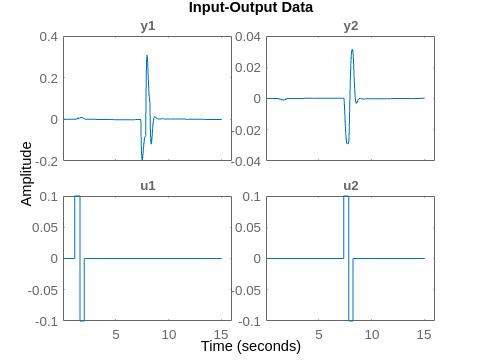

input = doublet;  %throttle
%input = zero;  %throttle
input2 = doublet2;  %elevator
out = sim('fullsys',paramStruct);
u1 = out.throttle;
u2 = out.elevator;
u = [u1 u2];
%y1 = squeeze(out.velocity)-v;
%y2 = squeeze(out.gamma);
y3 = squeeze(out.pitch_rate);
y4 = squeeze(out.aoa)-alpha_trim;
%y5 = squeeze(out.height)-h;
%y = [y1 y2 y3 y4 y5];
y = [y3 y4];
% np = [2; 2; 2; 2; 2];
% nz = [1; 1; 2; 1; 1];
np = [2 2; 2 2];
nz = [1 2; 1 1];
data = iddata(y,u,Ts);
plot(data)

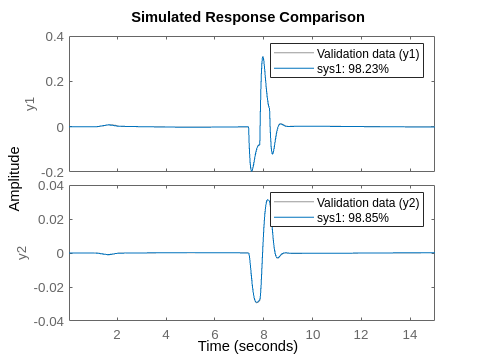

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)